# Plotting Beacon data in Global Frame

Using the Simulator, get the CreateRobot object that represents the current state of the robot 

Initialize Robot Constants

**COMPLETE THE CODE BELOW(A)**

%Initialize robot constants
robotRadius = robotObj.radius;
beacon_pose = [robotRadius; 0; 0];


Read the beacon data. 

%Read Beacon Data
tags = RealSenseTag(robotObj);

Read the robot pose

%Read the current position of the robot from the overhead
%  x, y and th, not a vector containing those values
[x, y, th]= genOverhead(robotObj);
robot_pose = [x; y; th];  

Using the *transform_points* function, transform the data from the sensor Frame to the robot Frame. Then transform the data from robot to global frame. The code below creates a plot of each beacon in the global frame. 

figure; 
hold on ;


for i = 1:size(tags,1)
    beacon_number = round(tags(i,2)); % Get beacon number
    dataxy_sensor = tags(i, 3:4)'; 
   
  

**COMPLETE THE CODE BELOW (B)**

 
   dataxy_robot = transform_points(beacon_pose,dataxy_sensor); % Transform data to robot frame
   dataxy_global = transform_points(robot_pose, dataxy_robot); % Transform data to global frame
  

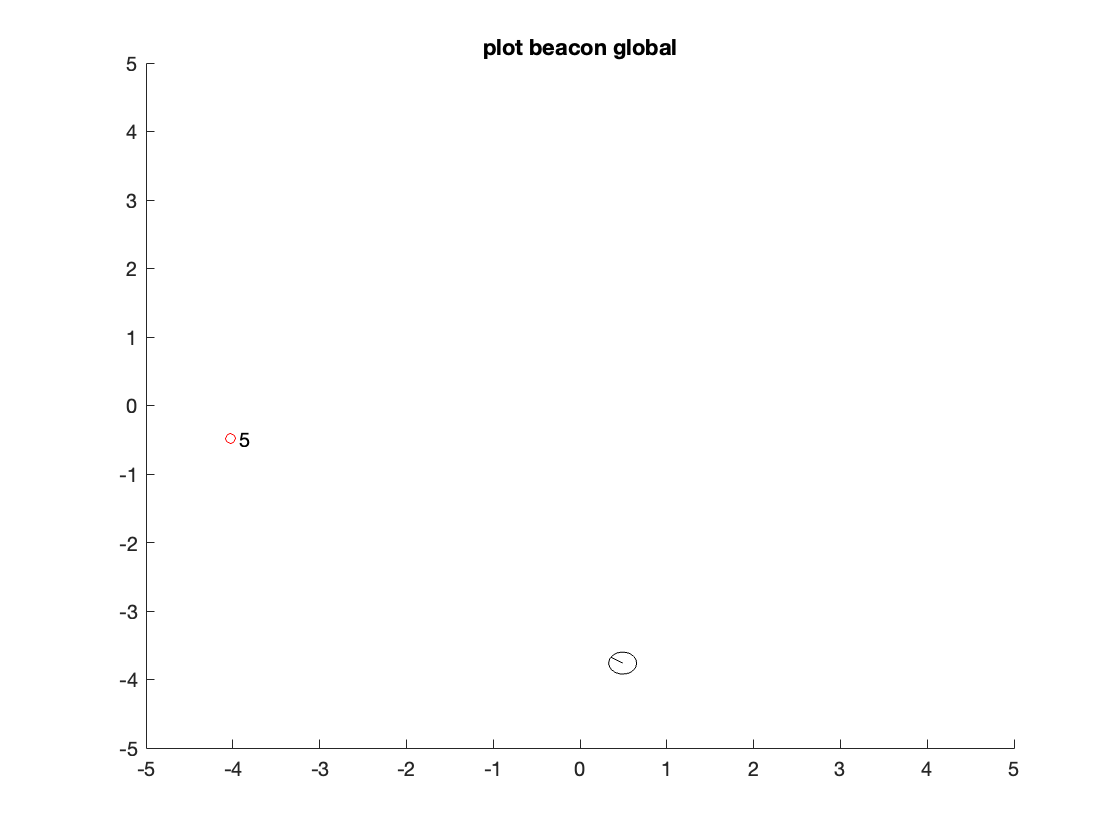

  
    plot(dataxy_global(1),dataxy_global(2),'ro','Markersize',5);
    text(dataxy_global(1)+.1,dataxy_global(2),num2str(beacon_number));
end

%Plots Robot position
th = linspace(0,2*pi,30);
plot(robot_pose(1)+robotRadius*cos(th),robot_pose(2)+robotRadius*sin(th),'k-')
plot([robot_pose(1),robot_pose(1)+robotRadius*cos(robot_pose(3))], ...
    [robot_pose(2),robot_pose(2)+robotRadius*sin(robot_pose(3))],'k-')

axis([-5 5 -5 5])
title('plot beacon global')
set(gcf,'Visible','on'); 
